# **Analysis 1**

Looking at traces, gating and cursory inactivation/activation kinetics. Didn't gate for APC inactivation, gated CRL

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
   '33 90 1 ug/mL no release',3:4,1,1:4,[0 0 0]; %1
   '33 90 no dox',3:4,11:12,1:4,[0 0 0]; %1
   '33 90 all dox',3:4,2:10,1:4,[0 0 0]; %1
   
   '34 90 1 ug/mL no release',7:8,1,1:4,[0 0 0]; %1
   '34 90 no dox',7:8,11:12,1:4,[0 0 0]; %1
   '34 90 all dox',7:8,2:10,1:4,[0 0 0]; %1
    
    };


load([dataDir 'E1099_data.mat'],'S_gated');

%S = loadData_E1099(conditions, dataDir);
%S_gated = gateData_E1099(S, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
folding =5;

numFrames = size(S_gated(1).apcNuc,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

conds=[3 6];

for i = 1:length(conds)
    data = S_gated(conds(i));
    S_gated(conds(i)).sigAct = NaN*ones(size(data.crlNuc(:,end)));
    for numcell = 1:length(data.crlNuc(:,end))
        if ~isnan(data.POI(numcell,2))
            S_gated(conds(i)).sigAct(numcell) = data.crlNuc(numcell,data.POI(numcell,2));
        end
    end
end

## **Plot traces aligned**

rng(3)
conds=[3 6];
poiAlign = [2];
alignNames = {'APC off'};
cols = 'kb';
cols = lines(2);
for p = 1:length(poiAlign)
    figure('Units', 'Inches', 'Position', [0, 0, 5, 4]);
    hold on
    frames = {};
    medSig = {};
    for i=1:length(conds)
        data = S_gated(conds(i));
        inds = ~isnan(data.POI(:,poiAlign(p))) & ...
            max(data.sigAct,[],2) > 100 & max(data.sigAct,[],2) < 150 & numFrames - data.POI(:,poiAlign(p)) > 30;
        if conds(i) == 3
            inds = inds & ~isnan(data.POI(:,3));
        end
            cells = find(inds);
        for numcell = randsample(cells,min([50 length(cells)]))'
            timeAligned = (xFrames-data.POI(numcell,poiAlign(p)))/framesPerHr;
            patchline(timeAligned(1:end-1),nansmoothm(data.crlNuc(numcell,1:end-1),7,'sgolay'),'EdgeColor',cols(i,:),'LineWidth',.5,'EdgeAlpha',.5);
            ylabel('mCherry fluorescence (AU)');
            xlabel('Time since APC off (hrs)');
%             ylim([0 155]);
            xlim([-2 8]);
        end
        [frames{i}, medSig{i}, semCRL] =get_median_trace(data.crlNuc(cells,:),data.POI(cells,poiAlign(p)),0);
        
        cells = length(cells)
    end
        for i=1:length(conds)
        plot((frames{i})/framesPerHr,medSig{i},'LineWidth',1.5,'Color',cols(i,:))

        end
    hold off
    
end

cells = 185

cells = 204

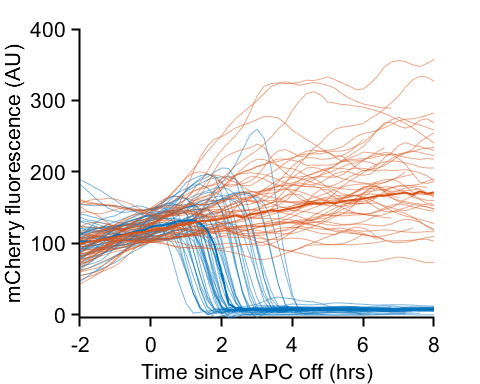

print_pdf([pwd() '\Figs\ND trace comp.pdf'])